Loaded cached CD(V,h) table from stardust_CD_table_cache.mat.


Mach 1.20 crossed at t=126.26 s (h=30.0 km, V=362.0 m/s) - freezing CD=1.116 (beta=79.4 kg/m^2) to ground.


Outcome: gamma cutoff at t=176.86 s (V=143.7 m/s, gamma=85.00 deg, h=19.98 km)


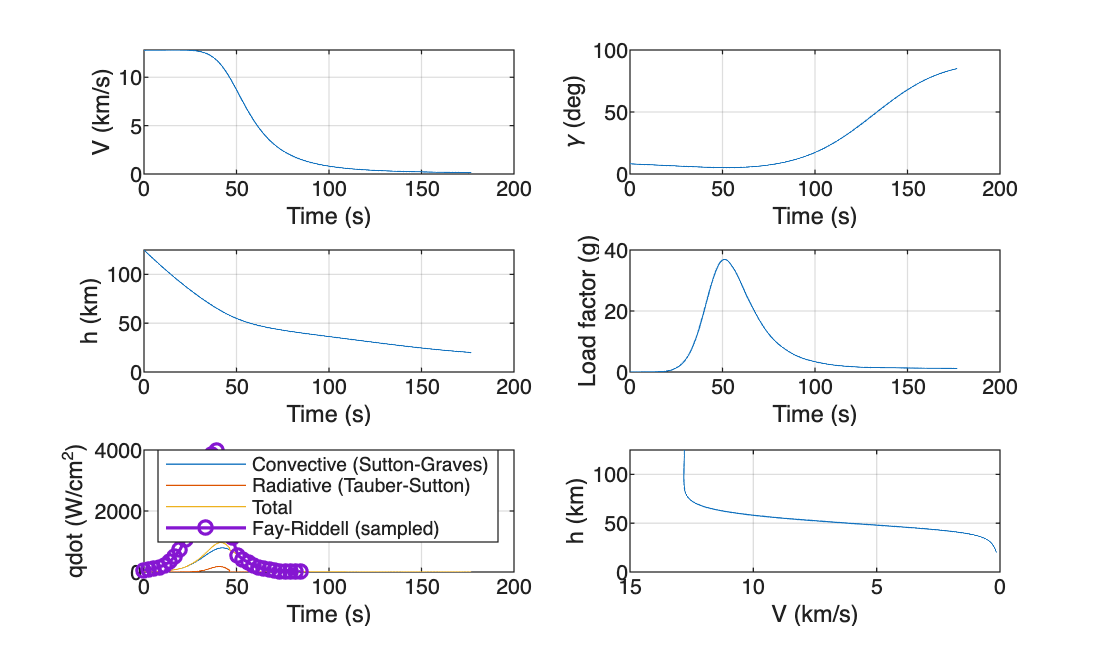

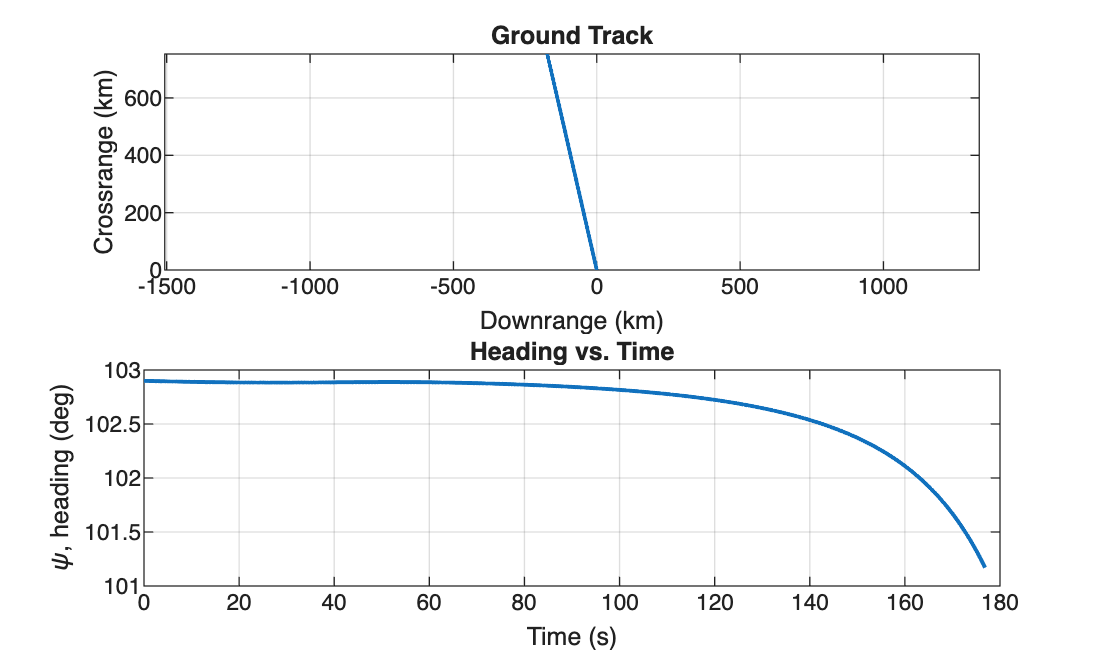

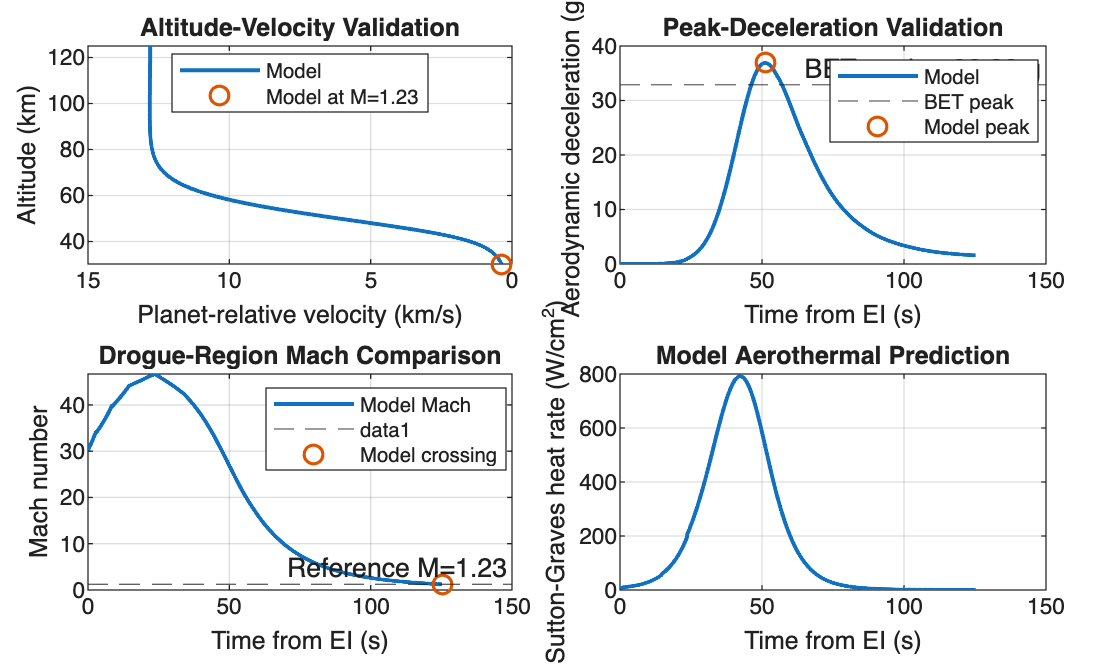


--- RUN SUMMARY ---


Outcome: gamma cutoff


motion_mode = nonplanar, aero_mode = equiflow, atm_model = layered, gravity_model = j2


  Final heading = 101.17 deg, downrange = -172.69 km, crossrange = 753.39 km


  CD frozen at Mach 1.20: t=126.26 s, CD=1.1159, beta=79.45 kg/m^2


Peak load factor: 36.89 g at t=51.1 s (h=54.1 km, V=8285.9 m/s)


Peak stagnation heat rate: 791.14 W/cm^2 at t=42.4 s (h=61.9 km, V=11095.6 m/s)


Total stagnation heat load: 21926.84 J/cm^2


Peak radiative heat rate (Tauber-Sutton): 177.50 W/cm^2 at t=40.6 s (V=11.50 km/s)


Radiative heat load: 2004.29 J/cm^2 (9.1% of convective heat load)


Peak combined (convective + radiative) heat rate: 963.91 W/cm^2



--- MAJOR UPGRADE #4: FAY-RIDDELL COMPARISON ---


Fay-Riddell peak (32 sampled points): 3980.34 W/cm^2 at t=39.15 s


Sutton-Graves at same point (exponential atmosphere): 751.87 W/cm^2


Sutton-Graves at same point (ATM.atm density): 751.79 W/cm^2


Integrated Fay-Riddell heat load: 85210.13 J/cm^2



--- STARDUST VALIDATION (Desai & Qualls, 2010) ---


Closed-form (Allen-Eggers, ballistic) peak deceleration = 60.96 g


Drogue-region (M=1.23): model dt=-12.66 s, dh=-0.817 km vs. reference


         validation_metric         model_value    reference_value    absolute_error    percent_error     units  
    ___________________________    ___________    _______________    ______________    _____________    ________

    {'Entry velocity'         }      12.799           12.799                   0                0       {'km/s'}
    {'Entry flight-path angle'}        8.21             8.21                   0                0       {'deg' }
    {'Entry altitude'         }      124.99           124.99                   0                0       {'km'  }
    {'Peak deceleration'      }      36.888            32.89              3.9976           12.154       {'g'   }
    {'Time at Mach 1.23'      }      125.24            137.9             -12.662          -9.1819       {'s'   }
    

%% AE 6355 - Individual Project - Stardust Entry Trajectory Simulation
% 3-DOF / 6-DOF point-mass entry simulation, validated against Stardust
% (Desai & Qualls, 2010). See accompanying report for equations and
% modeling assumptions.
%
% State (planar):    x = [V; gamma; h]
% State (nonplanar): x = [V; gamma; h; psi; phi; theta]
% gamma is positive below the local horizontal throughout.

clear; clc; close all;

%% -----------------------------------------------------------------
%% PLANET CONSTANTS AND STARDUST REFERENCE VALUES
%% -----------------------------------------------------------------
g0 = 9.81;                  % m/s^2
Re = 6378150;                % m

reference.V_EI                = 12799;
reference.gamma_EI_paper_deg  = -8.21;         % paper convention (negative descending)
reference.r_EI                = 6503.14e3;
reference.h_EI                = reference.r_EI - Re;
reference.peak_g_BET          = 32.89;
reference.peak_g_nominal      = 32.86;
reference.drogue_time         = 137.9;
reference.drogue_h            = 31.03e3;
reference.drogue_M            = 1.23;

%% -----------------------------------------------------------------
%% USER INPUTS
%% -----------------------------------------------------------------
% aero_mode     = 'constant' | 'equiflow'
% motion_mode   = 'planar'   | 'nonplanar'
% atm_model     = 'exponential' | 'layered'
% gravity_model = 'inverse_square' | 'j2'   (j2 only active if nonplanar)
%
% Each upgrade below is demonstrated by flipping ONE switch from the
% base (equiflow / planar / exponential / inverse_square) configuration.

V0     = reference.V_EI;
gamma0 = -deg2rad(reference.gamma_EI_paper_deg);   % sign-converted to model convention
h0     = reference.h_EI;

beta_const  = 61;           % kg/m^2 (aero_mode = 'constant' only)
LD_const    = 0;
sigma_const = 0;

aero_mode = 'equiflow';     % 'constant' or 'equiflow'

motion_mode = 'planar';     % 'planar' (3-state) or 'nonplanar' (6-state)
psi0   = deg2rad(102.9);    % rad, Stardust entry azimuth (Desai & Qualls 2010)
phi0   = 0;                 % rad, reference latitude
theta0 = 0;                 % rad, reference longitude

gravity_model = 'j2';   % 'inverse_square' or 'j2' (nonplanar only)
mu_earth    = 3.986e14;      % m^3/s^2
J2_earth    = 1.08263e-3;
omega_earth = 7.292115147e-5;% rad/s
K_ellip     = 1/298.257;

atm_model = 'layered';   % 'exponential' or 'layered'

% Stardust geometry
m_veh   = 46;
d_veh   = 0.8128;
rn      = 0.2202;
rb      = d_veh/2;
delta_c = 60*pi/180;
A_ref   = pi*rb^2;

% CPG properties / regime thresholds
gamma_air           = 1.4;
R_air               = 287;
T2_react_threshold  = 800;    % K
M_transonic_cutoff  = 1.2;

skip_altitude = h0 + 100;     % m, must exceed h0

V_grid = linspace(0, 14000, 20);
h_grid = linspace(0, 130000, 20);
assert(skip_altitude <= max(h_grid), 'skip_altitude must lie inside the aerodynamic-table altitude range.');

cpmax_formula_version = 3;
species_model = 'earth10';

CD_table_cache_file = 'stardust_CD_table_cache.mat';

if strcmp(aero_mode, 'equiflow')
    cache_valid = false;
    if isfile(CD_table_cache_file)
        try
            loaded = load(CD_table_cache_file, 'CD_interp', 'V_grid', 'h_grid', 'rn', 'rb', 'delta_c', ...
                'gamma_air', 'R_air', 'T2_react_threshold', 'M_transonic_cutoff', ...
                'cpmax_formula_version', 'species_model', 'd_veh');
            cache_valid = isequal(loaded.V_grid, V_grid) && isequal(loaded.h_grid, h_grid) ...
                && loaded.rn==rn && loaded.rb==rb && loaded.delta_c==delta_c ...
                && loaded.gamma_air==gamma_air && loaded.R_air==R_air ...
                && loaded.T2_react_threshold==T2_react_threshold ...
                && loaded.M_transonic_cutoff==M_transonic_cutoff ...
                && loaded.cpmax_formula_version==cpmax_formula_version ...
                && loaded.d_veh==d_veh ...
                && strcmp(loaded.species_model, species_model);
        catch
            cache_valid = false;
        end
    end

    if cache_valid
        CD_interp = loaded.CD_interp;
        fprintf('Loaded cached CD(V,h) table from %s.\n', CD_table_cache_file);
    else
        fprintf('Building CD(V,h) table...\n');
        CD_interp = build_stardust_CD_table(V_grid, h_grid, rn, rb, delta_c, species_model, ...
            gamma_air, R_air, T2_react_threshold, M_transonic_cutoff, d_veh);
        save(CD_table_cache_file, 'CD_interp', 'V_grid', 'h_grid', 'rn', 'rb', 'delta_c', ...
            'gamma_air', 'R_air', 'T2_react_threshold', 'M_transonic_cutoff', ...
            'cpmax_formula_version', 'species_model', 'd_veh');
    end
end

rho0 = 1.225;
H    = 7200;

%% -----------------------------------------------------------------
%% PARAMS STRUCT
%% -----------------------------------------------------------------
params.Re = Re;
switch aero_mode
    case 'constant'
        params.beta = @(V,h) beta_const;
        params.LD   = @(V,h) LD_const;
    case 'equiflow'
        params.beta = @(V,h) m_veh./(lookup_CD_checked(CD_interp, V_grid, h_grid, V, h).*A_ref);
        params.LD   = @(V,h) 0;
    otherwise
        error('Unknown aero_mode: %s', aero_mode);
end
params.sigma   = @(t) sigma_const;
params.g_fun   = @(h) g0*(Re/(Re+max(h,0)))^2;
params.rho_fun = @(h) get_density(max(h,0), atm_model, rho0, H);
params.gravity_model = gravity_model;
params.g_j2_fun = @(phi,h) g_j2(phi, max(h,0), mu_earth, J2_earth, omega_earth, Re, K_ellip);
params.omega = omega_earth;

LD_used = params.LD(0,0);

%% -----------------------------------------------------------------
%% ODE45 INTEGRATION
%% -----------------------------------------------------------------
switch motion_mode
    case 'planar'
        x0 = [V0; gamma0; h0];
        eom_fun = @EOM_3DOF;
        abstol_vec = [1e-3 1e-10 1e-3];
        gamma_cutoff = Inf;
    case 'nonplanar'
        x0 = [V0; gamma0; h0; psi0; phi0; theta0];
        eom_fun = @EOM_6DOF;
        abstol_vec = [1e-3 1e-10 1e-3 1e-10 1e-10 1e-10];
        gamma_cutoff = deg2rad(85);   % avoids EOM_6DOF's 1/cos(gamma) singularity; see report Sec. 2.2
    otherwise
        error('Unknown motion_mode: %s', motion_mode);
end
tspan = [0 2000];

freeze_time = NaN;
CD_freeze   = NaN;
beta_freeze = NaN;

ode_settings = {'RelTol',1e-8, 'AbsTol',abstol_vec, 'MaxStep',0.5};

if strcmp(aero_mode, 'equiflow')
    opts1 = odeset(ode_settings{:}, 'Events', ...
        @(t,x) mach_ground_skip_event(t,x,gamma_air,R_air,M_transonic_cutoff,skip_altitude,gamma_cutoff));
    [t1, x1, te1, xe1, ie1] = ode45(@(t,x) eom_fun(t, x, params), tspan, x0, opts1);

    if isempty(ie1)
        t = t1; x = x1; te = t1(end); xe = x1(end,:); outcome = 'time limit';
    elseif ie1(end) == 1
        t = t1; x = x1; te = te1; xe = xe1; outcome = 'ground impact';
    elseif ie1(end) == 3
        t = t1; x = x1; te = te1; xe = xe1; outcome = 'atmospheric skip-out';
    elseif ie1(end) == 4
        t = t1; x = x1; te = te1; xe = xe1; outcome = 'gamma cutoff';
    else
        V_freeze = xe1(1);
        h_freeze = xe1(3);
        CD_freeze   = lookup_CD_checked(CD_interp, V_grid, h_grid, V_freeze, h_freeze);
        beta_freeze = m_veh/(CD_freeze*A_ref);
        freeze_time = te1;
        fprintf('Mach %.2f crossed at t=%.2f s (h=%.1f km, V=%.1f m/s) - freezing CD=%.3f (beta=%.1f kg/m^2) to ground.\n', ...
            M_transonic_cutoff, te1, h_freeze/1000, V_freeze, CD_freeze, beta_freeze);

        params2 = params;
        params2.beta = @(V,h) beta_freeze;

        opts2 = odeset(ode_settings{:}, 'Events', @(t,x) ground_skip_event(t,x,skip_altitude,gamma_cutoff));
        [t2, x2, te2, xe2, ie2] = ode45(@(t,x) eom_fun(t, x, params2), [te1 tspan(2)], xe1, opts2);

        t = [t1; t2(2:end)];
        x = [x1; x2(2:end,:)];

        if isempty(ie2)
            te = t2(end); xe = x2(end,:); outcome = 'time limit';
        elseif ie2(end) == 1
            te = te2; xe = xe2; outcome = 'ground impact';
        elseif ie2(end) == 3
            te = te2; xe = xe2; outcome = 'gamma cutoff';
        else
            te = te2; xe = xe2; outcome = 'atmospheric skip-out';
        end
    end
else
    opts = odeset(ode_settings{:}, 'Events', @(t,x) ground_skip_event(t,x,skip_altitude,gamma_cutoff));
    [t, x, te, xe, ie] = ode45(@(t,x) eom_fun(t, x, params), tspan, x0, opts);
    if isempty(ie)
        te = t(end); xe = x(end,:); outcome = 'time limit';
    elseif ie(end) == 1
        outcome = 'ground impact';
    elseif ie(end) == 3
        outcome = 'gamma cutoff';
    else
        outcome = 'atmospheric skip-out';
    end
end

fprintf('Outcome: %s at t=%.2f s (V=%.1f m/s, gamma=%.2f deg, h=%.2f km)\n', ...
    outcome, te, xe(1), xe(2)*180/pi, xe(3)/1000);

V     = x(:,1);
gamma = x(:,2);
h     = x(:,3);

if strcmp(motion_mode, 'nonplanar')
    psi   = x(:,4);
    phi   = x(:,5);
    theta = x(:,6);
end

%% -----------------------------------------------------------------
%% POST-HOC: HEATING, DECELERATION
%% -----------------------------------------------------------------
rho_t = arrayfun(@(hh) get_density(max(hh,0), atm_model, rho0, H), h);

switch aero_mode
    case 'constant'
        beta_t = beta_const*ones(size(t));
    case 'equiflow'
        beta_t = nan(size(t));
        if ~isnan(freeze_time)
            pre_freeze = t <= freeze_time + 1e-9;
            beta_t(pre_freeze)  = m_veh./(arrayfun(@(vv,hh) lookup_CD_checked(CD_interp, V_grid, h_grid, vv, hh), ...
                V(pre_freeze), h(pre_freeze)) * A_ref);
            beta_t(~pre_freeze) = beta_freeze;
        else
            beta_t = m_veh./(arrayfun(@(vv,hh) lookup_CD_checked(CD_interp, V_grid, h_grid, vv, hh), V, h) * A_ref);
        end
end

% Sutton-Graves convective heating (report Eq. 7)
k_SG = 1.7415e-4;   % SI -> divide by 1e4 for W/cm^2
qdot_s  = k_SG*sqrt(rho_t/rn).*V.^3 / 1e4;
Q_total = trapz(t, qdot_s);
[qdot_peak, idx_heat] = max(qdot_s);

% Tauber-Sutton radiative heating, Earth (report Eq. 28-29)
C_E = 4.736e4;
b_E = 1.22;
a_earth = @(Vq,rhoq) min(1.072e6 * Vq.^(-1.88) .* rhoq.^(-0.325), 1.0);

V_kms = V/1000;
in_range_TS = V_kms >= 10 & V_kms <= 16;
qdot_rad = zeros(size(V));
a_vals = a_earth(V(in_range_TS), rho_t(in_range_TS));
qdot_rad(in_range_TS) = C_E * rn.^a_vals .* rho_t(in_range_TS).^b_E ...
    .* tauber_sutton_fV(V(in_range_TS), 'earth');   % W/cm^2
Q_rad_total = trapz(t, qdot_rad);
[qdot_rad_peak, idx_rad_peak] = max(qdot_rad);
qdot_total = qdot_s + qdot_rad;

% Fay-Riddell heating (report Eq. 14-18), sampled sparsely due to cost
% of the three equilibrium chemistry solves per point.
if strcmp(aero_mode, 'equiflow')
    n_FR_samples = 31;
    heating_region = find(qdot_s >= 0.01*qdot_peak);

    if isempty(heating_region)
        error('No heating region found for Fay-Riddell sampling.');
    end

    sample_idx = round(linspace(heating_region(1), heating_region(end), n_FR_samples));
    sample_idx = unique([sample_idx(:); idx_heat]);
    sample_idx = sort(sample_idx);

    [t_FR, qdot_FR] = compute_fay_riddell_heating( ...
        t(sample_idx), V(sample_idx), h(sample_idx), rn, species_model);

    [qdot_FR_peak, idx_FR_peak] = max(qdot_FR);

    % Sutton-Graves recomputed at the same points using ATM.atm density
    % for a consistent freestream comparison.
    qdot_SG_ATM = nan(size(t_FR));
    for k = 1:numel(t_FR)
        [~, ~, rho_ATM_k] = ATM.atm(max(h(sample_idx(k)),0)/1000);
        qdot_SG_ATM(k) = k_SG*sqrt(rho_ATM_k/rn)*V(sample_idx(k))^3/1e4;
    end

    FR_mask = t >= t_FR(1) & t <= t_FR(end);
    qdot_FR_full = nan(size(t));
    qdot_FR_full(FR_mask) = interp1(t_FR, qdot_FR, t(FR_mask), 'pchip');
    Q_FR = trapz(t(FR_mask), qdot_FR_full(FR_mask));
end

drag_accel  = rho_t.*V.^2./(2*beta_t);
aero_accel  = drag_accel.*sqrt(1 + LD_used^2);
load_factor = aero_accel/g0;
[load_peak, idx_load] = max(load_factor);

%% -----------------------------------------------------------------
%% MACH HISTORY / DROGUE-REGION MATCH (Stardust validation)
%% -----------------------------------------------------------------
if strcmp(aero_mode, 'equiflow')
    M_t = nan(size(t));
    for k = 1:numel(t)
        [~, Tinf_k, ~] = ATM.atm(max(h(k),0)/1000);
        a_k = sqrt(gamma_air*R_air*Tinf_k);
        M_t(k) = V(k)/a_k;
    end

    idx_Mref = find(M_t(1:end-1) >= reference.drogue_M & M_t(2:end) < reference.drogue_M, 1, 'first');

    t_Mref = NaN; h_Mref = NaN; V_Mref = NaN;
    if ~isempty(idx_Mref)
        M_pair = M_t(idx_Mref:idx_Mref+1);
        t_pair = t(idx_Mref:idx_Mref+1);
        t_Mref = interp1(flip(M_pair), flip(t_pair), reference.drogue_M);
        h_Mref = interp1(t, h, t_Mref);
        V_Mref = interp1(t, V, t_Mref);
    end

    validation_mask = M_t >= reference.drogue_M;
end

%% -----------------------------------------------------------------
%% PLOTS
%% -----------------------------------------------------------------
figure;
subplot(3,2,1); plot(t, V/1000); xlabel('Time (s)'); ylabel('V (km/s)'); grid on;
subplot(3,2,2); plot(t, gamma*180/pi); xlabel('Time (s)'); ylabel('\gamma (deg)'); grid on;
subplot(3,2,3); plot(t, h/1000); xlabel('Time (s)'); ylabel('h (km)'); grid on;
subplot(3,2,4); plot(t, load_factor); xlabel('Time (s)'); ylabel('Load factor (g)'); grid on;
subplot(3,2,5); plot(t, qdot_s, t, qdot_rad, t, qdot_total); hold on;
if strcmp(aero_mode, 'equiflow')
    plot(t_FR, qdot_FR, 'o-', 'MarkerSize',5, 'LineWidth',1.2);
    legend('Convective (Sutton-Graves)', 'Radiative (Tauber-Sutton)', 'Total', 'Fay-Riddell (sampled)', 'Location','best');
else
    legend('Convective (Sutton-Graves)', 'Radiative (Tauber-Sutton)', 'Total', 'Location','best');
end
xlabel('Time (s)'); ylabel('qdot (W/cm^2)'); grid on;
subplot(3,2,6); plot(V/1000, h/1000); set(gca,'XDir','reverse');
xlabel('V (km/s)'); ylabel('h (km)'); grid on;

if strcmp(motion_mode, 'nonplanar')
    figure;
    downrange_km = Re*(theta-theta0)/1000;   % local flat-Earth approximation
    crossrange_km = Re*(phi-phi0)/1000;
    subplot(2,1,1);
    plot(downrange_km, crossrange_km, 'LineWidth',1.5);
    xlabel('Downrange (km)'); ylabel('Crossrange (km)');
    title('Ground Track'); axis equal; grid on;
    subplot(2,1,2);
    plot(t, psi*180/pi, 'LineWidth',1.5);
    xlabel('Time (s)'); ylabel('\psi, heading (deg)');
    title('Heading vs. Time'); grid on;
end

if strcmp(aero_mode, 'equiflow')
    figure;
    tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

    nexttile;
    plot(V(validation_mask)/1000, h(validation_mask)/1000, 'LineWidth',1.5, 'DisplayName','Model');
    hold on;
    if isfinite(V_Mref)
        plot(V_Mref/1000, h_Mref/1000, 'o', 'MarkerSize',7, 'LineWidth',1.2, 'DisplayName','Model at M=1.23');
    end
    set(gca,'XDir','reverse');
    xlabel('Planet-relative velocity (km/s)'); ylabel('Altitude (km)');
    title('Altitude-Velocity Validation'); legend('Location','best'); grid on;

    nexttile;
    plot(t(validation_mask), load_factor(validation_mask), 'LineWidth',1.5, 'DisplayName','Model');
    hold on;
    yline(reference.peak_g_BET, '--', 'BET peak = 32.89 g', 'DisplayName','BET peak');
    plot(t(idx_load), load_peak, 'o', 'MarkerSize',7, 'LineWidth',1.2, 'DisplayName','Model peak');
    xlabel('Time from EI (s)'); ylabel('Aerodynamic deceleration (g)');
    title('Peak-Deceleration Validation'); legend('Location','best'); grid on;

    nexttile;
    plot(t(validation_mask), M_t(validation_mask), 'LineWidth',1.5, 'DisplayName','Model Mach');
    hold on;
    yline(reference.drogue_M, '--', 'Reference M=1.23');
    if isfinite(t_Mref)
        plot(t_Mref, reference.drogue_M, 'o', 'MarkerSize',7, 'LineWidth',1.2, 'DisplayName','Model crossing');
    end
    xlabel('Time from EI (s)'); ylabel('Mach number');
    title('Drogue-Region Mach Comparison'); legend('Location','best'); grid on;

    nexttile;
    plot(t(validation_mask), qdot_s(validation_mask), 'LineWidth',1.5);
    xlabel('Time from EI (s)'); ylabel('Sutton-Graves heat rate (W/cm^2)');
    title('Model Aerothermal Prediction'); grid on;
end

%% -----------------------------------------------------------------
%% SUMMARY
%% -----------------------------------------------------------------
fprintf('\n--- RUN SUMMARY ---\n');
fprintf('Outcome: %s\n', outcome);
fprintf('motion_mode = %s, aero_mode = %s, atm_model = %s, gravity_model = %s\n', ...
    motion_mode, aero_mode, atm_model, gravity_model);
if strcmp(motion_mode, 'nonplanar')
    fprintf('  Final heading = %.2f deg, downrange = %.2f km, crossrange = %.2f km\n', ...
        rad2deg(psi(end)), Re*(theta(end)-theta0)/1000, Re*(phi(end)-phi0)/1000);
end
if strcmp(aero_mode, 'equiflow') && ~isnan(freeze_time)
    fprintf('  CD frozen at Mach %.2f: t=%.2f s, CD=%.4f, beta=%.2f kg/m^2\n', ...
        M_transonic_cutoff, freeze_time, CD_freeze, beta_freeze);
end
fprintf('Peak load factor: %.2f g at t=%.1f s (h=%.1f km, V=%.1f m/s)\n', load_peak, t(idx_load), h(idx_load)/1000, V(idx_load));
fprintf('Peak stagnation heat rate: %.2f W/cm^2 at t=%.1f s (h=%.1f km, V=%.1f m/s)\n', qdot_peak, t(idx_heat), h(idx_heat)/1000, V(idx_heat));
fprintf('Total stagnation heat load: %.2f J/cm^2\n', Q_total);
fprintf('Peak radiative heat rate (Tauber-Sutton): %.2f W/cm^2 at t=%.1f s (V=%.2f km/s)\n', ...
    qdot_rad_peak, t(idx_rad_peak), V_kms(idx_rad_peak));
fprintf('Radiative heat load: %.2f J/cm^2 (%.1f%% of convective heat load)\n', ...
    Q_rad_total, 100*Q_rad_total/Q_total);
fprintf('Peak combined (convective + radiative) heat rate: %.2f W/cm^2\n', max(qdot_total));
if strcmp(aero_mode, 'equiflow')
    fprintf('\n--- FAY-RIDDELL COMPARISON ---\n');
    fprintf('Fay-Riddell peak (%d sampled points): %.2f W/cm^2 at t=%.2f s\n', ...
        numel(t_FR), qdot_FR_peak, t_FR(idx_FR_peak));
    fprintf('Sutton-Graves at same point (exponential atmosphere): %.2f W/cm^2\n', ...
        qdot_s(sample_idx(idx_FR_peak)));
    fprintf('Sutton-Graves at same point (ATM.atm density): %.2f W/cm^2\n', ...
        qdot_SG_ATM(idx_FR_peak));
    fprintf('Integrated Fay-Riddell heat load: %.2f J/cm^2\n', Q_FR);
end

%% -----------------------------------------------------------------
%% STARDUST VALIDATION
%% -----------------------------------------------------------------
if strcmp(aero_mode, 'equiflow')
    if isfinite(t_Mref)
        drogue_time_error = t_Mref - reference.drogue_time;
        drogue_h_error     = h_Mref - reference.drogue_h;
    else
        drogue_time_error = NaN;
        drogue_h_error     = NaN;
    end

    % Closed-form ballistic check (Allen-Eggers), independent of the
    % numerical integration.
    n_max_closed_form = V0^2*sin(gamma0)/(53.3*H);

    fprintf('\n--- STARDUST VALIDATION (Desai & Qualls, 2010) ---\n');
    fprintf('Closed-form (Allen-Eggers, ballistic) peak deceleration = %.2f g\n', n_max_closed_form);
    if isfinite(t_Mref)
        fprintf('Drogue-region (M=%.2f): model dt=%+.2f s, dh=%+.3f km vs. reference\n', ...
            reference.drogue_M, drogue_time_error, drogue_h_error/1000);
    else
        fprintf('Model did not cross M = %.2f.\n', reference.drogue_M);
    end

    validation_metric = {'Entry velocity'; 'Entry flight-path angle'; 'Entry altitude'; ...
        'Peak deceleration'; 'Time at Mach 1.23'; 'Altitude at Mach 1.23'};
    model_value = [V0/1000; rad2deg(gamma0); h0/1000; load_peak; t_Mref; h_Mref/1000];
    reference_value = [reference.V_EI/1000; -reference.gamma_EI_paper_deg; reference.h_EI/1000; ...
        reference.peak_g_BET; reference.drogue_time; reference.drogue_h/1000];
    units = {'km/s'; 'deg'; 'km'; 'g'; 's'; 'km'};

    absolute_error = model_value - reference_value;
    percent_error = 100*absolute_error./reference_value;
    percent_error(1:3) = 0;   % entry conditions are prescribed inputs, not predictions

    validation_table = table(validation_metric, model_value, reference_value, absolute_error, percent_error, units);
    disp(validation_table);
    writetable(validation_table, 'Stardust_validation_results.csv');
end

% Standalone check: J2 gravity model vs. known equatorial/polar surface
% gravity reference values.
phi_ref = [0, pi/2];
phi_label = {'Equatorial (phi=0)', 'Polar (phi=90 deg)'};
g_ref = [9.780, 9.832];

g_model = nan(size(phi_ref));
for i = 1:length(phi_ref)
    g_model(i) = g_j2(phi_ref(i), 0, mu_earth, J2_earth, omega_earth, Re, K_ellip);
end

g_err = 100*(g_model - g_ref)./g_ref;

T_j2_check = table(phi_label', rad2deg(phi_ref)', g_model', g_ref', g_err', ...
    'VariableNames', {'Latitude_case','Latitude_deg','g_model_ms2','g_ref_ms2','pct_err'});
writetable(T_j2_check, 'appendix_j2_gravity_verification.csv');


%% ===================================================================
%% LOCAL FUNCTIONS
%% ===================================================================

function [value, isterminal, direction] = ground_skip_event(t, x, skip_altitude, gamma_cutoff)
% gamma_cutoff: Inf disables the gamma-cutoff event (planar mode).
% Nonplanar mode passes a real cutoff (85 deg) to terminate before
% EOM_6DOF's 1/cos(gamma) singularity.
    h     = x(3);
    gamma = x(2);
    value      = [h; h - skip_altitude; gamma_cutoff - gamma];
    isterminal = [1; 1; 1];
    direction  = [-1; +1; -1];
end

function [value, isterminal, direction] = mach_ground_skip_event(t, x, gamma_air, R_air, M_cutoff, skip_altitude, gamma_cutoff)
    V     = x(1);
    h     = x(3);
    gamma = x(2);
    [~, Tinf, ~] = ATM.atm(h/1000);
    a_sound = sqrt(gamma_air*R_air*Tinf);
    M = V/a_sound;

    value      = [h; M - M_cutoff; h - skip_altitude; gamma_cutoff - gamma];
    isterminal = [1; 1; 1; 1];
    direction  = [-1; -1; +1; -1];
end

function CD = lookup_CD_checked(CD_interp, V_grid, h_grid, V, h)
    h_q = max(h, h_grid(1));
    if V < V_grid(1) || V > V_grid(end) || h_q > h_grid(end)
        error('CD table query out of bounds: V=%.1f m/s, h=%.2f km', V, h/1000);
    end
    CD = CD_interp(V, h_q);
    if ~isscalar(CD) || ~isfinite(CD) || CD <= 0
        error('Invalid interpolated CD at V=%.1f m/s, h=%.3f km.', V, h/1000);
    end
end

function rho2 = extract_shock_density(shock)
    candidate_names = {'Density','density','Rho','rho'};
    rho2 = NaN;
    for k = 1:numel(candidate_names)
        name = candidate_names{k};
        if isstruct(shock) && isfield(shock, name)
            rho2 = shock.(name);
            break;
        elseif isobject(shock) && isprop(shock, name)
            rho2 = shock.(name);
            break;
        end
    end
    if ~isscalar(rho2) || ~isfinite(rho2) || rho2 <= 0
        error('Could not obtain a valid post-shock density from EquiFlow.');
    end
end

function CD_interp = build_stardust_CD_table(V_grid, h_grid, rn, rb, delta_c, species_model, ...
    gamma_air, R_air, T2_react_threshold, M_transonic_cutoff, d_veh)
% Precomputes CD(V,h): Modified Newtonian (continuum) bridged to
% free-molecular via Knudsen number. See report Sec. 2.1, 2.4.

    ef = EquiFlow(species_model);

    nV = length(V_grid);
    nH = length(h_grid);
    CD_table = zeros(nV, nH);
    total_points = nV*nH;
    points_done = 0;

    area_ratio_term = (rn/rb)^2;

    kB   = 1.380649e-23;   % J/K
    d_N2 = 364e-12;        % m
    Tw   = 300;            % K

    fprintf('Building %dx%d CD(V,h) table (%d points)...\n', nV, nH, total_points);
    build_tic = tic;
    next_progress_pct = 10;

    for j = 1:nH
        h_km = h_grid(j)/1000;
        [Pinf, Tinf, Rhoinf] = ATM.atm(h_km);
        a_sound  = sqrt(gamma_air*R_air*Tinf);
        V_cutoff = M_transonic_cutoff*a_sound;

        lambda = kB*Tinf / (pi*sqrt(2)*d_N2^2*Pinf);
        Kn = lambda/d_veh;

        for i = 1:nV
            V_eval = max(V_grid(i), V_cutoff);
            M = V_eval/a_sound;

            P2_P1_cpg     = 1 + (2*gamma_air/(gamma_air+1))*(M^2 - 1);
            rho2_rho1_cpg = ((gamma_air+1)*M^2) / ((gamma_air-1)*M^2 + 2);
            T2_cpg        = Tinf * (P2_P1_cpg / rho2_rho1_cpg);

            if T2_cpg > T2_react_threshold
                shock = ef.NormalShock(Tinf, Pinf, Rhoinf, V_eval);
                rho2  = extract_shock_density(shock);
                if rho2 <= Rhoinf
                    error('Normal-shock density did not increase at V=%.1f m/s, h=%.1f km.', V_eval, h_km);
                end
                epsilon = Rhoinf/rho2;
            else
                epsilon = 1/rho2_rho1_cpg;
            end
            Cpmax = 2 - epsilon;

            CA_cont = Cpmax*( 0.5*(1-sin(delta_c)^4)*area_ratio_term ...
                        + sin(delta_c)^2*(1 - area_ratio_term*cos(delta_c)^2) );
            CA_cont = max(CA_cont, eps);

            if Kn <= 1e-3
                CA = CA_cont;
            else
                s = V_eval/sqrt(2*R_air*Tinf);
                Tw_ratio_term = sqrt(pi*Tw/Tinf);

                CD_FM_sphere = 2 + (2/(3*s))*Tw_ratio_term;
                CD_FM_cone = sin(delta_c)^2 + (1/s)*Tw_ratio_term*sin(delta_c) ...
                    + 2*cos(delta_c)^2;
                CA_FM = area_ratio_term*CD_FM_sphere + (1-area_ratio_term)*CD_FM_cone;

                if Kn >= 10
                    CA = CA_FM;
                else
                    phi = pi*(3/8 + (1/8)*log10(Kn));
                    CA = CA_cont + (CA_FM - CA_cont)*sin(phi)^2;
                end
            end

            CD_table(i,j) = max(CA, eps);
            points_done = points_done + 1;

            pct_done = 100*points_done/total_points;
            if pct_done >= next_progress_pct
                elapsed = toc(build_tic);
                est_total = elapsed/points_done*total_points;
                fprintf('  %.0f%% done, elapsed %.1f min, est. total %.1f min\n', pct_done, elapsed/60, est_total/60);
                next_progress_pct = next_progress_pct + 10;
            end
        end
    end
    fprintf('CD(V,h) table build complete in %.1f min.\n', toc(build_tic)/60);

    CD_interp = griddedInterpolant({V_grid, h_grid}, CD_table, 'linear', 'none');
end

function [t_out, qdot_FR] = compute_fay_riddell_heating( ...
        t_sample, V_sample, h_sample, rn, species_model)
% Fay-Riddell stagnation-point heating: equilibrium normal-shock/edge
% states, fully catalytic wall, Le=1, cold wall Tw=300K, MN stagnation
% pressure. See report Sec. 2.3.

    Tw = 300;             % K
    ef = EquiFlow(species_model);

    n = numel(t_sample);
    qdot_FR = nan(n,1);

    for k = 1:n
        Vinf = V_sample(k);
        h_km = max(h_sample(k),0)/1000;

        [Pinf, Tinf, Rhoinf] = ATM.atm(h_km);

        shock = ef.NormalShock(Tinf, Pinf, Rhoinf, Vinf);

        rho2 = shock.Density;
        V2   = shock.DownstreamVelocity;

        if ~isfinite(rho2) || rho2 <= Rhoinf
            error(['Invalid post-shock density at t=%.3f s: ' ...
                   'rho2=%.6e, rhoinf=%.6e kg/m^3.'], ...
                   t_sample(k), rho2, Rhoinf);
        end

        if ~isfinite(V2) || V2 < 0
            error('Invalid downstream velocity at t=%.3f s.', t_sample(k));
        end

        epsilon = Rhoinf/rho2;
        Cpmax   = 2 - epsilon;

        qinf = 0.5*Rhoinf*Vinf^2;
        Pe   = Pinf + Cpmax*qinf;

        h0e = shock.Enthalpy + 0.5*V2^2;

        edge = ef.SolveHP(h0e, Pe, Transport=true);

        rhoe = edge.Density;
        mue  = edge.Viscosity;
        Cpe  = edge.Cp;
        kfe  = edge.ThermalConductivity;

        if any(~isfinite([rhoe, mue, Cpe, kfe])) || ...
                rhoe <= 0 || mue <= 0 || Cpe <= 0 || kfe <= 0
            error('Invalid equilibrium edge properties at t=%.3f s.', t_sample(k));
        end

        wall = ef.SolveTP(Tw, Pe, Transport=true);

        rhow = wall.Density;
        muw  = wall.Viscosity;
        hw   = wall.Enthalpy;

        if any(~isfinite([rhow, muw, hw])) || rhow <= 0 || muw <= 0
            error('Invalid equilibrium wall properties at t=%.3f s.', t_sample(k));
        end

        Pr_e = mue*Cpe/kfe;

        due_dx = (1/rn)*sqrt(2*(Pe-Pinf)/rhoe);
        enthalpy_difference = h0e - hw;

        if ~isfinite(Pr_e) || Pr_e <= 0
            error('Invalid edge Prandtl number at t=%.3f s.', t_sample(k));
        end

        if ~isfinite(due_dx) || due_dx <= 0
            error('Invalid stagnation-point velocity gradient at t=%.3f s.', t_sample(k));
        end

        if ~isfinite(enthalpy_difference) || enthalpy_difference <= 0
            error(['Nonpositive h0e-hw at t=%.3f s: ' ...
                   'h0e=%.6e, hw=%.6e J/kg.'], ...
                   t_sample(k), h0e, hw);
        end

        qdot_FR(k) = 0.763*Pr_e^(-0.6)*(rhoe*mue)^0.4*(rhow*muw)^0.1 ...
            *sqrt(due_dx)*enthalpy_difference/1e4;

        if ~isfinite(qdot_FR(k)) || qdot_FR(k) < 0
            error('Invalid Fay-Riddell heat flux at t=%.3f s.', t_sample(k));
        end
    end

    t_out = t_sample(:);
end

function g = g_j2(phi, h, mu, J2, omega, r_equator, K)
% J2 oblateness gravity with rotation and ellipticity (report Eq. 25-27).
    R0 = r_equator*(1 - K*sin(phi)^2);
    R  = R0 + h;
    D  = K*(1 - h/R0)*sin(2*phi);
    g = (mu/R^2)*(1 - 0.75*J2*(1 - 3*cos(2*phi))) - R*omega^2*cos(phi)*cos(phi-D);
end

function rho = get_density(h, atm_model, rho0, H)
    switch atm_model
        case 'exponential'
            rho = rho0*exp(-h/H);
        case 'layered'
            [~, ~, rho] = std_atm_layered(h);
        otherwise
            error('Unknown atm_model: %s', atm_model);
    end
end

function fV = tauber_sutton_fV(V, planet)
% Tabulated Tauber-Sutton f(V), Table 1 (Tauber & Sutton, 1991), V in
% m/s. Log-space pchip interpolation.
    switch planet
        case 'earth'
            V_table = [9000,9250,9500,9750,10000,10250,10500,10750,11000, ...
                       11500,12000,12500,13000,13500,14000,14500,15000,15500,16000];
            fV_table = [1.5,4.3,9.7,19.5,35,55,81,115,151,238,359,495,660,850,1065,1313,1550,1780,2040];
        case 'mars'
            V_table = [6000,6150,6300,6500,6700,6900,7000,7200,7400,7600,7800,8000,8200,8400,8600,8800,9000];
            fV_table = [0.2,1.0,1.95,3.42,5.1,7.1,8.1,10.2,12.5,14.8,17.1,19.2,21.4,24.1,26.0,28.9,32.8];
        otherwise
            error('Unknown planet for tauber_sutton_fV: %s', planet);
    end

    fV = exp(interp1(V_table, log(fV_table), V, 'pchip', 'extrap'));
end

function [T, P, rho] = std_atm_layered(h_m)
% Layered US Standard Atmosphere: 1976 (0-86 km, geopotential, 7
% layers) + 1962 extension (86-150 km, geometric, layer-varying MW).
% See report Sec. 2.5.

    g0  = 9.80665;
    R   = 287.05;
    r_E = 6356766;      % m

    H_geop = h_m * r_E / (r_E + h_m);

    H_base = [0, 11000, 20000, 32000, 47000, 51000, 71000, 86000];
    T_base = [288.15, 216.65, 216.65, 228.65, 270.65, 270.65, 214.65, 186.87];
    L_1976 = [-6.5e-3, 0, 1e-3, 2.8e-3, 0, -2.8e-3, -2e-3, 0];

    P_base = zeros(size(H_base));
    P_base(1) = 101325;
    for i = 2:length(H_base)
        dHb = H_base(i) - H_base(i-1);
        if abs(L_1976(i-1)) < 1e-12
            P_base(i) = P_base(i-1) * exp(-g0*dHb/(R*T_base(i-1)));
        else
            P_base(i) = P_base(i-1) * (T_base(i)/T_base(i-1))^(-g0/(R*L_1976(i-1)));
        end
    end

    if h_m < 86000
        layer = find(H_geop >= H_base, 1, 'last');
        T_l = T_base(layer);
        L_l = L_1976(layer);
        dH = H_geop - H_base(layer);
        T = T_l + L_l*dH;
        if abs(L_l) < 1e-12
            P = P_base(layer) * exp(-g0*dH/(R*T_l));
        else
            P = P_base(layer) * (T/T_l)^(-g0/(R*L_l));
        end
        rho = P/(R*T);
        return;
    end

    Z_base   = [86, 100, 110, 120, 150] * 1e3;
    Tm_base  = [186.945, 210.65, 260.65, 360.65];
    Lz       = [1.6481e-3, 5.0e-3, 10.0e-3, 20.0e-3];
    P_base2  = [0.34313, 0.030075, 0.0073544, 0.0025217];
    MW       = [28.9644, 28.88, 28.56, 28.08];

    R_bar = 8314.0;
    b     = 3.31e-7;

    Z = h_m;
    if Z >= Z_base(end)
        layer2 = 4;
    else
        layer2 = find(Z >= Z_base(1:4), 1, 'last');
    end

    Tm_i = Tm_base(layer2);
    Lz_i = Lz(layer2);
    P_i  = P_base2(layer2);
    MW_i = MW(layer2);
    z_i  = Z_base(layer2);
    R_i  = R_bar / MW_i;

    T = Tm_i + Lz_i*(Z - z_i);
    rho_i = P_i * MW_i / (R_bar * Tm_i);

    POW_p   = -(g0/(R_i*Lz_i)) * (1 + b*(Tm_i/Lz_i - z_i));
    POW_rho = -(g0/(R_i*Lz_i)) * (R_i*Lz_i/g0 + 1 + b*(Tm_i/Lz_i - z_i));
    exp_term = exp(g0*b/(R_i*Lz_i) * (Z - z_i));

    P   = P_i   * (T/Tm_i)^POW_p   * exp_term;
    rho = rho_i * (T/Tm_i)^POW_rho * exp_term;
end

function xdot = EOM_3DOF(t, x, params)
% 3-DOF planar EOM (report Eq. 1-3). gamma positive below horizontal.
    V     = x(1);
    gamma = x(2);
    h     = x(3);

    if V <= 0
        error('Nonpositive velocity at t=%.6f s.', t);
    end

    h_env = max(h, 0);
    Re    = params.Re;
    beta  = params.beta(V, h_env);
    LD    = params.LD(V, h_env);
    sigma = params.sigma(t);
    g     = params.g_fun(h_env);
    rho   = params.rho_fun(h_env);

    dVdt     = -rho*V^2/(2*beta) + g*sin(gamma);
    dgammadt = -V*cos(gamma)/(Re + h) - (rho*V/(2*beta))*LD*cos(sigma) + g*cos(gamma)/V;
    dhdt     = -V*sin(gamma);

    xdot = [dVdt; dgammadt; dhdt];
end

function xdot = EOM_6DOF(t, x, params)
% 6-state non-planar EOM, Earth-fixed rotating frame (report Eq. 8-13).
% gamma positive below horizontal (course convention negated; see
% report Sec. 2.2).
    V     = x(1);
    gamma = x(2);
    h     = x(3);
    psi   = x(4);
    phi   = x(5);

    if V <= 0
        error('Nonpositive velocity at t=%.6f s.', t);
    end

    h_env = max(h, 0);
    Re    = params.Re;
    beta  = params.beta(V, h_env);
    LD    = params.LD(V, h_env);
    sigma = params.sigma(t);
    if isfield(params,'gravity_model') && strcmp(params.gravity_model, 'j2')
        g = params.g_j2_fun(phi, h_env);
    else
        g = params.g_fun(h_env);
    end
    rho   = params.rho_fun(h_env);
    r     = Re + h;
    omega = params.omega;

    dVdt = -rho*V^2/(2*beta) + g*sin(gamma) ...
        - omega^2*r*cos(phi)*(sin(gamma)*cos(phi) + cos(gamma)*sin(phi)*sin(psi));

    dgammadt = -(rho*V/(2*beta))*LD*cos(sigma) + g*cos(gamma)/V - V*cos(gamma)/r ...
        - 2*omega*cos(phi)*cos(psi) ...
        - (omega^2*r/V)*cos(phi)*(cos(gamma)*cos(phi) - sin(gamma)*sin(phi)*sin(psi));

    dhdt = -V*sin(gamma);

    dpsidt = (rho*V/(2*beta))*LD*sin(sigma)/cos(gamma) ...
        - V*cos(gamma)*cos(psi)*tan(phi)/r ...
        - 2*omega*(tan(gamma)*cos(phi)*sin(psi) + sin(phi)) ...
        - (omega^2*r/(V*cos(gamma)))*sin(phi)*cos(phi)*cos(psi);

    dphidt   = (V/r)*cos(gamma)*sin(psi);
    dthetadt = (V/r)*cos(gamma)*cos(psi)/cos(phi);

    xdot = [dVdt; dgammadt; dhdt; dpsidt; dphidt; dthetadt];
end